%% Task B: Calculate Landing Point of Rocket Trajectory
% This script determines the landing point of the rocket trajectory.
% Includes error estimation by comparing results with different step sizes.
% Implements linear interpolation from scratch to refine landing point.

%% Clear environment
clear all
close all
clc

%% Define initial parameters
% Initial conditions
v_init = 21;             % Initial velocity magnitude (m/s)
theta_init = 81;         % Initial angle (degrees)
theta = deg2rad(theta_init); % Convert to radians

% Simulation parameters
t_start = 0;             % Start time (s)
t_burn = 0.08;           % Burn time end (s)
t_end = 4;               % Simulation end time (s)
F = 1;                   % Force during burn time (N)

% Step sizes for error analysis
h_values = [0.01, 0.005, 0.0025]; % Time steps for different precision levels
n_steps = length(h_values);

%% Part 1: Study the error in raw landing point with different step sizes
% Initialize arrays to store results
landing_points = zeros(n_steps, 1);
y_at_landing = zeros(n_steps, 1);
idx_landing_values = zeros(n_steps, 1);
diff_landing = nan(n_steps, 1); % First difference will be NaN

fprintf('=== Part 1: Error in Raw Landing Point ===\n');

=== Part 1: Error in Raw Landing Point ===


fprintf('Running simulations with different step sizes...\n');

Running simulations with different step sizes...



% Store trajectories for later visualization
all_trajectories = cell(n_steps, 1);
all_times = cell(n_steps, 1);

% Run simulations with different step sizes
for i = 1:n_steps
    h = h_values(i);
    
    % Simulate rocket trajectory
    [z, t] = simulate_rocket(t_start, t_burn, t_end, h, F, v_init, theta);
    
    % Store trajectory
    all_trajectories{i} = z;
    all_times{i} = t;
    
    % Find when rocket returns to ground level through manual iteration
    landing_idx = 0;
    for j = 2:length(z(2,:))
        if z(2,j-1) > 0 && z(2,j) <= 0
            landing_idx = j;
            break;
        end
    end
    
    % If landing point found
    if landing_idx > 0
        % Simple raw estimate (point where y first becomes <= 0)
        landing_points(i) = z(1, landing_idx);
        y_at_landing(i) = z(2, landing_idx);
        idx_landing_values(i) = landing_idx;
        

    else
        warning('No landing point found for step size h = %.6f', h);
        landing_points(i) = NaN;
        y_at_landing(i) = NaN;
        idx_landing_values(i) = NaN;
    end
end

% Calculate differences between consecutive step sizes
for i = 2:n_steps
    diff_landing(i) = abs(landing_points(i) - landing_points(i-1));
end



%% Part 2: Study the interpolation error with different step sizes for interpolation
fprintf('\n=== Part 2: Error in Interpolated Landing Point ===\n');


=== Part 2: Error in Interpolated Landing Point ===



% We'll use the finest trajectory for this analysis
z_finest = all_trajectories{end};
t_finest = all_times{end};
idx_landing_finest = idx_landing_values(end);

% Different step sizes for selecting adjacent points (in terms of indices)
step_sizes = [1, 2, 4];
n_interp_steps = length(step_sizes);

% Initialize arrays to store interpolation results
landing_points_interp = zeros(n_interp_steps, 1);
t_at_landing_interp = zeros(n_interp_steps, 1);
interp_diff = nan(n_interp_steps, 1); % First difference will be NaN

for i = 1:n_interp_steps
    step = step_sizes(i);
    
    % Find interpolated landing point using linear interpolation
    [landing_point, landing_time, coeffs] = find_landing_point_interp(z_finest, t_finest, idx_landing_finest, step);
    
    % Store results
    landing_points_interp(i) = landing_point;
    t_at_landing_interp(i) = landing_time;
    
    fprintf('Linear Interpolation step %d: Landing point = %.20f m at t = %.6f s\n', ...
            step, landing_points_interp(i), t_at_landing_interp(i));
end

Linear Interpolation step 1: Landing point = 8.81286990154086602445 m at t = 3.716811 s
Linear Interpolation step 2: Landing point = 8.81286813945276747972 m at t = 3.717041 s
Linear Interpolation step 4: Landing point = 8.81286460824050266183 m at t = 3.717224 s



% Calculate differences between consecutive interpolation steps
for i = 2:n_interp_steps
    interp_diff(i) = abs(landing_points_interp(i) - landing_points_interp(i-1));
end

% Print differences
fprintf('\nDifferences between consecutive interpolation steps:\n');


Differences between consecutive interpolation steps:


for i = 1:n_interp_steps
    if isnan(interp_diff(i))
        fprintf('interp_diff%d = NaN\n', i-1);
    else
        fprintf('interp_diff%d = abs(interp_point_%d - interp_point_%d) = %.8e m\n', ...
                i-1, i-1, i, interp_diff(i));
    end
end

interp_diff0 = NaN


interp_diff1 = abs(interp_point_1 - interp_point_2) = 1.76208810e-06 m
interp_diff2 = abs(interp_point_2 - interp_point_3) = 3.53121226e-06 m



% Kvadratisk interpolation för varje steg
fprintf('\n=== Kvadratisk Interpolation av Landningspunkt ===\n');


=== Kvadratisk Interpolation av Landningspunkt ===



landing_points_quad = zeros(n_interp_steps, 1);
for i = 1:n_interp_steps
    step = step_sizes(i);
    [landing_quad, t_quad, ~] = find_landing_point_quadratic(z_finest, t_finest, idx_landing_finest, step);
    landing_points_quad(i) = landing_quad;
    
    fprintf('Quadratic interpolation step %d: Landing point = %.20f m\n', ...
            step, landing_quad);
end

Quadratic interpolation step 1: Landing point = 8.81287245055581003328 m
Quadratic interpolation step 2: Landing point = 8.81287244804930303133 m
Quadratic interpolation step 4: Landing point = 8.81287243802336739407 m



% Skillnader mellan kvadratisk och linjär
fprintf('\n=== Jämförelse Linjär vs Kvadratisk ===\n');


=== Jämförelse Linjär vs Kvadratisk ===


for i = 1:n_interp_steps
    diff_lq = abs(landing_points_interp(i) - landing_points_quad(i));
    fprintf('Step %d: |Linear - Quadratic| = %.10e m\n', i, diff_lq);
end

Step 1: |Linear - Quadratic| = 2.5490149440e-06 m
Step 2: |Linear - Quadratic| = 4.3085965356e-06 m
Step 3: |Linear - Quadratic| = 7.8297828647e-06 m




%% Part 3: Combine Results and Estimate Final Error
fprintf('\n=== Part 3: Final Results ===\n');


=== Part 3: Final Results ===



% Best raw estimate (finest grid)
best_raw = landing_points(end);
raw_error = diff_landing(end);

% Best interpolated estimate (smallest interpolation step)
best_interp = landing_points_interp(1);
interp_error = interp_diff(2);

% Combined error (RSS - Root Sum Square)
combined_error = sqrt(raw_error^2 + interp_error^2);

fprintf('Best raw landing point: %.15f ± %.5e m\n', best_raw, raw_error);

Best raw landing point: 8.815043639402854 ± 3.94008e-03 m


fprintf('Best interpolated landing point: %.15f ± %.5e m\n', best_interp, interp_error);

Best interpolated landing point: 8.812869901540866 ± 1.76209e-06 m


fprintf('Final result:\n    Landing point = %.15f ± (%.5e + %.5e)', best_interp, combined_error, raw_error);

Final result:
    Landing point = 8.812869901540866 ± (3.94008e-03 + 3.94008e-03)

fprintf('    Landing point = %.15f ± (%.5e)\n', best_interp, combined_error);

    Landing point = 8.812869901540866 ± (3.94008e-03)


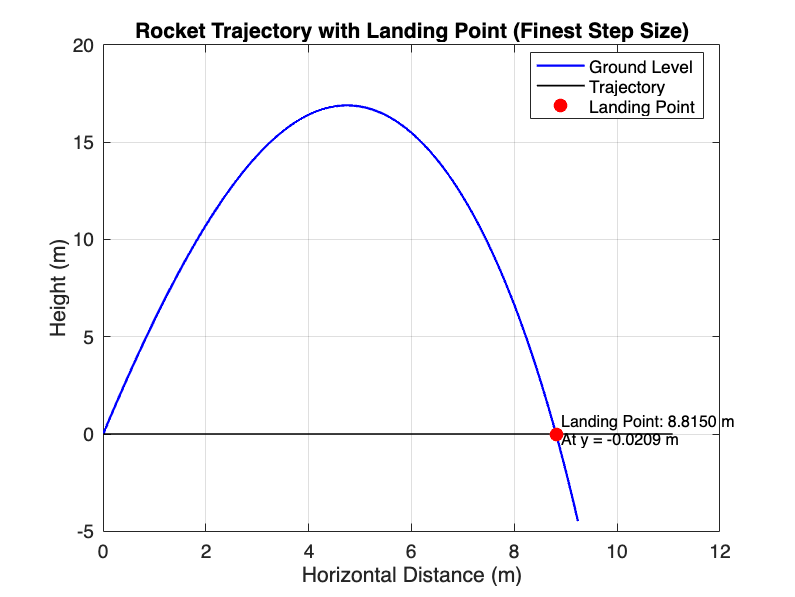


%% Visualize results
% 1. Plot the trajectory for raw finest step size
%    Mark the landing point
figure(1);
finest_idx = length(h_values); % Index of the finest step size
trajectory = all_trajectories{finest_idx};
time = all_times{finest_idx};
idx_landing = idx_landing_values(finest_idx);

% Plot the full trajectory
plot(trajectory(1,:), trajectory(2,:), 'b-', 'LineWidth', 1.5);
hold on;

% Plot the ground level
plot([0, max(trajectory(1,:))*1.2], [0, 0], 'k-', 'LineWidth', 1);

% Mark the landing point
plot(landing_points(finest_idx), 0, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');

% Add a text label for the landing point
text(landing_points(finest_idx)+0.1, 0.2, ...
    sprintf('Landing Point: %.4f m\nAt y = %.4f m', landing_points(finest_idx), y_at_landing(finest_idx)), ...
    'FontSize', 10);

% Add grid, labels, and title
grid on;
xlabel('Horizontal Distance (m)');
ylabel('Height (m)');
title('Rocket Trajectory with Landing Point (Finest Step Size)');
set(gca, 'FontSize', 12);
legend('Ground Level', 'Trajectory', 'Landing Point', 'Location', 'best');
hold off;

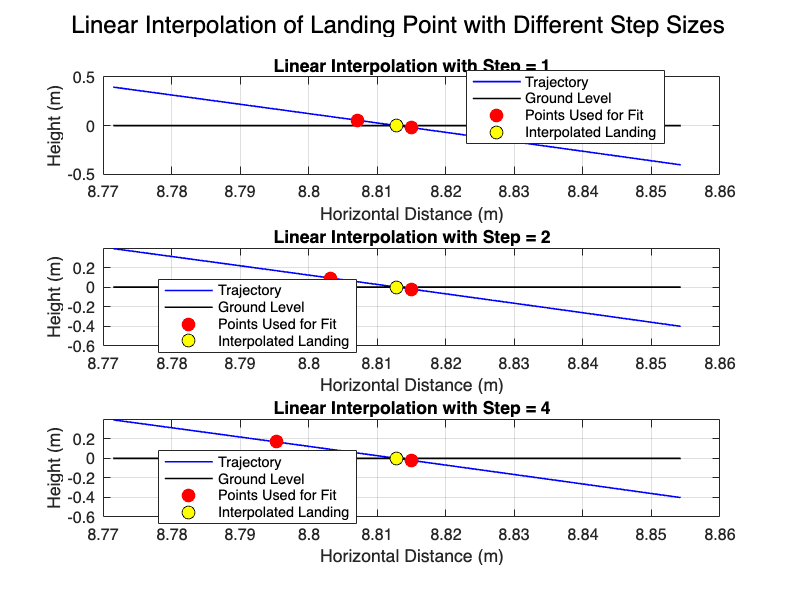


% 2. Visualize the interpolation with different step sizes
figure(2);
z_finest = all_trajectories{end};
t_finest = all_times{end};
idx_landing_finest = idx_landing_values(end);

% Create 3 subplots, one for each interpolation step size
for i = 1:length(step_sizes)
    step = step_sizes(i);
    
    % Create the subplot
    subplot(3, 1, i);
    
    % Determine the indices of points used for interpolation
    if idx_landing_finest > 1
        pre_landing_idx = idx_landing_finest - 1;
    else
        pre_landing_idx = 1;
    end
    
    % Define range of points to plot (focus on the landing area)
    plot_range = max(1, pre_landing_idx-10):min(idx_landing_finest+10, length(z_finest(1,:)));
    
    % Plot trajectory segment
    plot(z_finest(1, plot_range), z_finest(2, plot_range), 'b-', 'LineWidth', 1);
    hold on;
    
    % Plot ground level
    x_range = [min(z_finest(1, plot_range)), max(z_finest(1, plot_range))];
    plot(x_range, [0, 0], 'k-', 'LineWidth', 1);
    
    % Get points for interpolation based on step size
    if pre_landing_idx > step
        idx_range = [pre_landing_idx-step, idx_landing_finest];
    else
        idx_range = [1, pre_landing_idx];
    end
    
    % Add the landing point
    %idx_range = [pre_landing_idx, idx_landing_finest];
    %idx_range = [pre_landing_idx-step, idx_landing_finest];
    % Get coordinate values for the selected points
    x_vals = z_finest(1, idx_range);
    y_vals = z_finest(2, idx_range);
    t_vals = t_finest(idx_range);
    
    % Perform linear interpolation between the last above-ground point and first below-ground point
    [landing_point, landing_time, coeffs] = find_landing_point_interp(z_finest, t_finest, idx_landing_finest, step);
    
    % Extract coefficients for the plot
    if length(coeffs) == 2 % Linear interpolation
        m = coeffs(1);
        b = coeffs(2);
        
        % Create fine grid for plotting the line
        x_fine = linspace(x_vals(end-1)-0.1, x_vals(end)+0.1, 100);
        y_fine = m*x_fine + b;
    end
    
    % Plot the linear interpolation
    %plot(x_fine, y_fine, 'g-', 'LineWidth', 1.5);
    
    % Mark the points used for interpolation
    plot(x_vals(end-1:end), y_vals(end-1:end), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    
    % Mark the interpolated landing point
    plot(landing_point, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'y');
    
    % Add labels and title
    xlabel('Horizontal Distance (m)');
    ylabel('Height (m)');
    title(sprintf('Linear Interpolation with Step = %d', step));
    
    % Add legend
    legend('Trajectory','Ground Level', 'Points Used for Fit', 'Interpolated Landing', ...
           'Location', 'best');
    
    % Add text with interpolation results
    text(max(xlim)*0.6, max(ylim)*0.9, ...
        sprintf('Landing Point: %.6f m\nAt t = %.4f s', landing_point, landing_time), ...
        'FontSize', 8, 'BackgroundColor', [1 1 0.8]);
    
    grid on;
    hold off;
    
    % Keep the same dimensions for all subplots
    if i == 1
        xlim_val = xlim;
        ylim_val = ylim;
    else
        xlim(xlim_val);
        ylim(ylim_val);
    end
end

% Adjust the layout
sgtitle('Linear Interpolation of Landing Point with Different Step Sizes');
set(gcf, 'Position', [100, 100, 800, 600]);


%% Heiper Functions

function [z, t] = simulate_rocket(t_start, t_burn, t_end, h, F, v_init, theta)
    % Initial conditions
    x0 = 0;
    y0 = 0;
    [vx0, vy0] = decompose_velocity(v_init, theta);
    
    % Phase 1: With thrust (t_start to t_burn)
    [z1, t1] = runge_kutta(t_start, t_burn, h, F, x0, y0, vx0, vy0, theta);
    
    % Phase 2: No thrust (t_burn to t_end)
    [z2, t2] = runge_kutta(t_burn, t_end, h, 0, z1(1,end), z1(2,end), z1(3,end), z1(4,end), theta);
    
    % Combine results
    z = [z1, z2(:,2:end)];
    t = [t1, t2(2:end)];
end

function [z, t] = runge_kutta(t_start, t_end, h, F, x0, y0, vx0, vy0, theta)
    % Generate time values
    t = t_start:h:t_end;
    N = length(t);
    
    % Initialize solution matrix [x, y, vx, vy]
    z = zeros(4, N);
    z(:, 1) = [x0; y0; vx0; vy0];
    
    % Runge-Kutta integration
    for i = 1:N-1
        t_current = t(i);
        z_current = z(:, i);
        
        % Four steps of RK4 method
        k1 = rocket_ode(t_current, z_current, F, theta);
        k2 = rocket_ode(t_current + h/2, z_current + (h/2)*k1, F, theta);
        k3 = rocket_ode(t_current + h/2, z_current + (h/2)*k2, F, theta);
        k4 = rocket_ode(t_current + h, z_current + h*k3, F, theta);
        
        % Update solution
        z(:, i+1) = z_current + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
    end
end

function dzdt = rocket_ode(t, z, F_val, theta_init)
    % Extract state variables
    x = z(1);      % Position x
    y = z(2);      % Position y
    vx = z(3);     % Velocity x
    vy = z(4);     % Velocity y
    
    % Physical parameters
    g = 9.82;      % Gravity (m/s²)
    m0 = 0.05;     % Initial mass (kg)
    k_x = 0.001;   % Air resistance coefficient x
    k_y = 0.001;   % Air resistance coefficient y
    k = 0.08;      % Mass flow rate (kg/s)
    
    % Calculate current mass
    if t <= 0.08
        m = m0 - k*t;
    else
        m = m0 - k*0.08;
    end
    
    % Calculate thrust force
    if t <= 0.08
        F = F_val;
    else
        F = 0;
    end
    
    % Calculate angle
    if t <= 0
        phi = theta_init;
    else
        phi = atan2(vy, vx);  % Using atan2 for correct quadrant
    end
    
    % Calculate speed
    V = sqrt(vx^2 + vy^2);
    
    % Differential equations
    dzdt = zeros(4, 1);
    dzdt(1) = vx;
    dzdt(2) = vy;
    dzdt(3) = (F*cos(phi) - k_x*vx*V)/m;
    dzdt(4) = (F*sin(phi) - k_y*vy*V)/m - g;
end

function [vx, vy] = decompose_velocity(v, theta)
    vx = v*cos(theta);
    vy = v*sin(theta);
end

function [landing_point, landing_time, coeffs] = find_landing_point_interp(z, t, idx_landing, step)
    % Find landing point using linear interpolation
    % with specified step size for selecting adjacent points
    y_pos = z(2,:);
    x_pos = z(1,:);
    
    % Determine pre-landing index (the point just before crossing y=0)
    if idx_landing > 1
        pre_landing_idx = idx_landing - 1;
    else
        pre_landing_idx = 1;
        warning('Landing occurs at or before the first point');
    end
    
    % Determine points to use based on step size
    if pre_landing_idx > step
        p1_idx = pre_landing_idx - step;
    else
        p1_idx = 1;
    end
    
    % The two points on either side of the ground crossing
    x1 = x_pos(p1_idx);
    y1 = y_pos(p1_idx);
    x2 = x_pos(idx_landing);
    y2 = y_pos(idx_landing);

    
    t1 = t(pre_landing_idx);
    t2 = t(idx_landing);
    
    % Linear interpolation: y = kx + m
    k = (y2 - y1) / (x2 - x1);
    m = y1 - k*x1;
    
    % Find x when y = 0: 0 = kx + m => x = -m/k
    landing_point = -m / k;
    
    % Find t at landing point using linear interpolation
    landing_time = t1 + (t2 - t1) * (landing_point - x1) / (x2 - x1);
    
    % Return coefficients for plotting
    coeffs = [k, m];
end


function [landing_point, landing_time, coeffs] = find_landing_point_quadratic(z, t, idx_landing, step)
    % Kvadratisk interpolation för att hitta landningspunkten (där y=0)
    
    y_pos = z(2,:);
    x_pos = z(1,:);
    t_vals = t;
    
    % Index före landning
    pre_idx = idx_landing - 1;
    
    % Välj tre punkter runt landningen
    if pre_idx > step && idx_landing + step <= length(x_pos)
        idx_range = [pre_idx - step, pre_idx, pre_idx + step];
    else
        idx_range = max(1, pre_idx-1):min(length(x_pos), idx_landing+1);
        if length(idx_range) < 3
            idx_range = [1, 2, 3];  % Fallback
        end
    end

    x_vals = x_pos(idx_range);
    y_vals = y_pos(idx_range);
    t_vals = t_vals(idx_range);
    
    % Lös för koefficienter a, b, c i y = ax^2 + bx + c
    A = [x_vals(1)^2, x_vals(1), 1;
         x_vals(2)^2, x_vals(2), 1;
         x_vals(3)^2, x_vals(3), 1];
    coeffs = A \ y_vals(:);
    a = coeffs(1); b = coeffs(2); c = coeffs(3);
    
    % Lös för x när y=0: ax^2 + bx + c = 0 med egen implementation
    discriminant = b^2 - 4*a*c;
    
    if discriminant < 0
        warning('Diskriminanten är negativ – ingen reell lösning');
        landing_point = x_vals(2);  % fallback till mittpunkt
    else
        sqrt_disc = sqrt(discriminant);
        
        x1 = (-b + sqrt_disc) / (2*a);
        x2 = (-b - sqrt_disc) / (2*a);
        
        % Avgör vilket av x1 eller x2 som ligger inom intervallet
        x_min = min(x_vals);
        x_max = max(x_vals);
        
        if x1 >= x_min && x1 <= x_max
            landing_point = x1;
        elseif x2 >= x_min && x2 <= x_max
            landing_point = x2;
        else
            warning('Ingen giltig rot inom intervallet – använder närmaste punkt');
            landing_point = x_vals(2);  % fallback till mittpunkt
        end
    end

    
    % Interpolera tid linjärt (approx)
    t1 = t_vals(1); t2 = t_vals(end);
    x1 = x_vals(1); x2 = x_vals(end);
    landing_time = t1 + (t2 - t1) * (landing_point - x1) / (x2 - x1);
end
